# 2. aet2-Klausur  2Ea/2Eb  vom  8.6.2016

## 1.

clear all
clc
Z1_ = 20 + 250*j;
Z2_ = 220 - 10*j;
Z3_ = 35 - 159*j;
Z4_ = 89.9486 + 82.3562i

Z3_ = 89.9486 + 82.3562i



U12_ = 400*exp(j*(-2*pi/3*0));
U23_ = 400*exp(j*(-2*pi/3*1));
U31_ = 400*exp(j*(-2*pi/3*2));

Y1_ = 1/Z1_;
Y2_ = 1/Z2_;
Y3_ = 1/Z3_;

Z_ = stern2dreieck(Z1_, Z2_, Z3_, false);
Z12_ = Z_.Ra;
Z23_ = Z_.Rb;
Z31_ = Z_.Rc;

I12_ = U12_/Z12_;
I23_ = U23_/Z23_;
I31_ = U31_/Z31_;

I12=strcat(num2str(abs(I12_)), "A /_ ", num2str(rad2deg(angle(I12_))), "°")

I12 = "0.50527A /_ -42.3398°"

I23=strcat(num2str(abs(I23_)), "A /_ ", num2str(rad2deg(angle(I23_))), "°")

I23 = "1.0391A /_ -119.3907°"

I31=strcat(num2str(abs(I31_)), "A /_ ", num2str(rad2deg(angle(I31_))), "°")

I31 = "0.91241A /_ 32.5806°"


% Knotensatz !!!!!
I1_ = I12_ - I31_;
I2_ = I23_ - I12_;
I3_ = I31_ - I23_;

I1=strcat(num2str(abs(I1_)), "A /_ ", num2str(rad2deg(angle(I1_))), "°")

I1 = "0.92082A /_ -115.4261°"

I2=strcat(num2str(abs(I2_)), "A /_ ", num2str(rad2deg(angle(I2_))), "°")

I2 = "1.0486A /_ -147.3974°"

I3=strcat(num2str(abs(I3_)), "A /_ ", num2str(rad2deg(angle(I3_))), "°")

I3 = "1.8936A /_ 47.523°"



%
U1ms_ = I1_ * Z1_;
U2ms_ = I2_ * Z2_;
U3ms_ = I3_ * Z3_;
U1ms=strcat(num2str(abs(U1ms_)), "V /_ ", num2str(rad2deg(angle(U1ms_))), "°")

U1ms = "230.9401V /_ -30°"

U2ms=strcat(num2str(abs(U2ms_)), "V /_ ", num2str(rad2deg(angle(U2ms_))), "°")

U2ms = "230.9401V /_ -150°"

U3ms=strcat(num2str(abs(U3ms_)), "V /_ ", num2str(rad2deg(angle(U3ms_))), "°")

U3ms = "230.9401V /_ 90°"


Umms_ = (U1ms_ + U2ms_ + U3ms_ ) /3;
%Umms_ = - (U1m_*Y1_ + U2m_*Y2_ + U3m_*Y3_) / (Y1_+Y2_+Y3_)
Umms=strcat(num2str(abs(Umms_)), "V /_ ", num2str(rad2deg(angle(Umms_))), "°")

Umms = "1.1684e-05V /_ -128.7146°"


U1m_ = U1ms_ - Umms_;
U2m_ = U2ms_ - Umms_;
U3m_ = U3ms_ - Umms_;

U1m=strcat(num2str(abs(U1m_)), "V /_ ", num2str(rad2deg(angle(U1m_))), "°")

U1m = "230.9401V /_ -30°"

U2m=strcat(num2str(abs(U2m_)), "V /_ ", num2str(rad2deg(angle(U2m_))), "°")

U2m = "230.9401V /_ -150°"

U3m=strcat(num2str(abs(U3m_)), "V /_ ", num2str(rad2deg(angle(U3m_))), "°")

U3m = "230.9401V /_ 90°"


P1 = real(U12_*I1_')

P1 = -158.1400

P3 = real(-U23_*I3_')

P3 = 739.5643

P = P1+P3

P = 581.4243


% 
syms Y4_;
Y4_=solve( (U1m_*Y1_ + U2m_*Y2_ + U3m_*Y4_)/(Y1_+Y2_+Y4_)==0 )

$$Y4\_ = \frac{49950844814412535669572761903502204532948992}{8259535258715047192145624542011825236540475569}-\frac{137203736210391849003340829462567349668282368}{24778605776145141576436873626035475709621426707}\,\mathrm{i}$$

Z4_ = double(1/Y4_)

Z4_ = 89.9486 + 82.3562i

## 4.

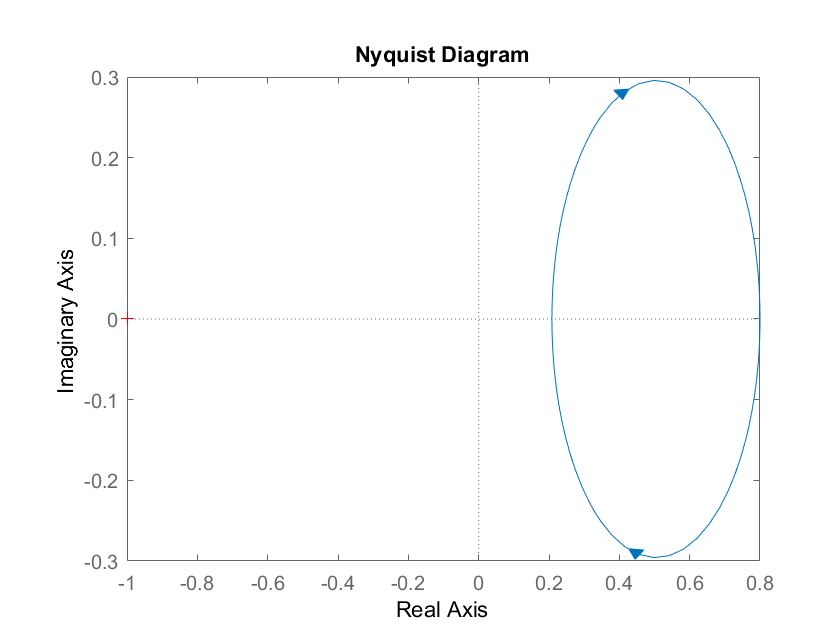

clear all
clc

s=tf('s');
R=1;
C=100e-6;

H2 = 4*R + 1/(4*s*C);
H1 = 5*R + 1/(s*C) + 1/(s*5*C);

nyquist(H2/H1)

% Kreismittelpunkt:
m=1/2;
r=2/5;
phimax = atand(r/m)

phimax = 38.6598

## 5. c)

clear; clc;
U=230; I=1; P=150;
S=U*I

S = 230

Q=sqrt(S^2-P^2)

Q = 174.3560

phibe=acos(P/S)

phibe = 0.8603

f=50; w=2*pi*f;
U_=U*exp(0);
rad2deg(phibe)          % deg

ans = 49.2943

Q=P*j*tan(phibe)

Q = 0.0000e+00 + 1.7436e+02i

S_=P+Q

S_ = 1.5000e+02 + 1.7436e+02i

Y_=(S_/U^2)'

Y_ = 0.0028 - 0.0033i

Z_=1/Y_

Z_ = 1.5000e+02 + 1.7436e+02i

1. R + L

"R + L"

ans = "R + L"

%Rs=(U^2)/P
Rs=real(Z_)

Rs = 150.0000

Xls=-imag(Z_');
Ls=Xls/(w)

Ls = 0.5550

Zrsl_=Rs+j*w*Ls;

2. R + C

"R + C"

ans = "R + C"

Rs=Rs

Rs = 150.0000

Xcs=imag(Z_);
Cs=1/(w*Xls)

Cs = 1.8256e-05

Zrsc_=Rs+1/(j*w*Cs);

3. R || L

"R || L"

ans = "R || L"

Gp=real(Y_);
Rp=1/Gp

Rp = 352.6667

Blp=-imag(Y_);
Lp=1/(w*Blp)

Lp = 0.9658

Zrpl_=par(Rp, j*w*Lp);

4. R || C

"R || C"

ans = "R || C"

Rp=1/Gp

Rp = 352.6667

Bcp=Blp;
Cp=Bcp/(w)

Cp = 1.0491e-05

Zrpc_=par(Rp, 1/(j*w*Cp));

Kontrolle

Srpc_ = U^2/Zrpc_'

Srpc_ = 1.5000e+02 - 1.7436e+02i

Srpl_ = U^2/Zrpl_'

Srpl_ = 1.5000e+02 + 1.7436e+02i

Srsc_ = U^2/Zrsc_'

Srsc_ = 1.5000e+02 - 1.7436e+02i

Srsl_ = U^2/Zrsl_'

Srsl_ = 1.5000e+02 + 1.7436e+02i